# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 11-Nov-2020 09:47:53

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 27);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
% % % opts.VariableNames = ["Timestamp", "Date", "Time", "EntubeSE_L1N_Cond_MeasV", "P41600_L1N_Meter_MeasV", "EntubeZ_L1N_Meter_MeasV", "EntubeSE_L2N_Meter_MeasV", "HCT100_L1N_AHU_MeasV", "HCT025_L1N_AHU_MeasV", ...
% % %     "HCT200_L1N_Cond_MeasV", "HCT025_L1N_Cond_MeasV", ...
% % %     "P7800_L2N_Meter_MeasV", "VT7D_L1N_AHU_MeasV", "VT7D_L2N_AHU_MeasV", "VT7D_L2N_Cond_MeasV", "EntubeSE_L1N_Cond_CalcV", "P41600_L1N_Meter_CalcA", "EntubeZ_L1N_Meter_CalcV", "EntubeSE_L2N_Meter_CalcV", ...
% % %     "HCT100_L1N_AHU_CalcA", "HCT025_L1N_AHU_CalcA", "HCT200_L1N_Cond_CalcA", "HCT025_L1N_Cond_CalcA", "P7800_L2N_Meter_CalcA", "VT7D_L1N_AHU_CalcV", "VT7D_L2N_AHU_CalcV", "VT7D_L2N_Cond_CalcV"];
% % % opts.VariableTypes = ["datetime", "datetime", "datetime", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

opts.VariableNames = ["Timestamp", "Date", "Time", "EntubeSE_L1N_Cond_CalcV", "P41600_L1N_Meter_CalcA", "EntubeZ_L1N_Meter_CalcV", "EntubeSE_L2N_Meter_CalcV", ...
    "HCT100_L1N_AHU_CalcA", "HCT025_L1N_AHU_CalcA", "HCT200_L1N_Cond_CalcA", "HCT025_L1N_Cond_CalcA", "P7800_L2N_Meter_CalcA", "VT7D_L1N_AHU_CalcV", "VT7D_L2N_AHU_CalcV", "VT7D_L2N_Cond_CalcV"];
opts.VariableTypes = ["datetime", "datetime", "datetime", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];


% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Timestamp", "InputFormat", "MM/dd/yyyy hh:mm:ss.SSS aa");
opts = setvaropts(opts, "Date", "InputFormat", "MM/dd/yyyy");
opts = setvaropts(opts, "Time", "InputFormat", "hh:mm:ss.SSS aa");
% Import the data

inv = 0;

### Import data  for the whole house P, Q, PF, Harmonics calculations

% Meter - Whole House Data
% % % PowerData1 = readtable("C:\NZERTF Power Data\WholeHouseData\NI_9223_9222_9222N_2021-02-19_143719_1.txt", opts);
% % % PowerData2 = readtable("C:\NZERTF Power Data\WholeHouseData\NI_9223_9222_9222N_2021-02-19_143720_2.txt", opts);
% % % PowerData3 = readtable("C:\NZERTF Power Data\WholeHouseData\NI_9223_9222_9222N_2021-02-19_143721_3.txt", opts);


% Inverter
% % % inv = 1;
% % % PowerData1 = readtable("C:\NZERTF Power Data\Temp\NI_9223_9222_9222N_2021-02-17_152100_600.txt", opts);



% Dryer
% % % PowerData1 = readtable("C:\NZERTF Power Data\Temp\NI_9223_9222_9222N_2021-02-17_154010_1242.txt", opts);


% HP
PowerData1 = readtable("C:\NZERTF Power Data\Temp\NI_9223_9222_9222N_2021-02-17_132401_1000.csv", opts);


% Clothes Washer
% % % PowerData1 = readtable("C:\NZERTF Power Data\Temp\NI_9223_9222_9222N_2021-02-17_161043_2700.txt", opts);


fft_rangeStart = 1; %10001;

% 12 cycles for fs = 300000 @ 60 Hz fundamental
fft_rangeEnd   = 60000; %20000; %100000;

Calculating RMS Voltages

[https://www.mathworks.com/help/signal/ug/measure-total-harmonic-distortion.html](https://www.mathworks.com/help/signal/ug/measure-total-harmonic-distortion.html)

THD is calculated by r = 10*log10(harmSum/harmPow(1)), where harmSum is the sum of harmonic powers for all frequencies excluding the fundamental freq. 

The output (harmpow) of the thd function is giving in dB = 10*log10(power amplitude).

fs = 300000; %25000; % sample rate
oh  = 50;     % number of harmonics to include in the THD calculations

fundFreq = 60; % 60 Hz

% Meter
if (inv == 1) 
    invertCTsForAllExpectInv = 1;
else
   invertCTsForAllExpectInv = -1;
end

% Voltage L1-N
V_L1 = PowerData1.EntubeZ_L1N_Meter_CalcV(2:end);
% Voltage L2-N
V_L2 = PowerData1.EntubeSE_L2N_Meter_CalcV(2:end);
% Current L1-N
C_L1 = PowerData1.P41600_L1N_Meter_CalcA(2:end) .* invertCTsForAllExpectInv;
% Current L2-N
C_L2 = PowerData1.P7800_L2N_Meter_CalcA(2:end) .* invertCTsForAllExpectInv;


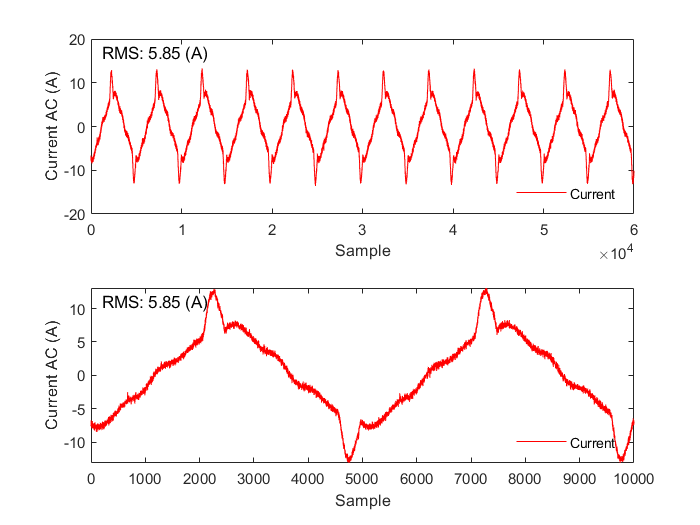

% Select a data channel
data = C_L2(fft_rangeStart:fft_rangeEnd);
inputs = [];
inputs.data = data;
plot_rms(inputs, 'timedata')

% Test THDFFT_V2 
inputs = [];
inputs.data = data';
inputs.fs = fs;
inputs.Ff = fundFreq;
inputs.harmonic_order = oh;
outputs = THDFFT_V2(inputs);

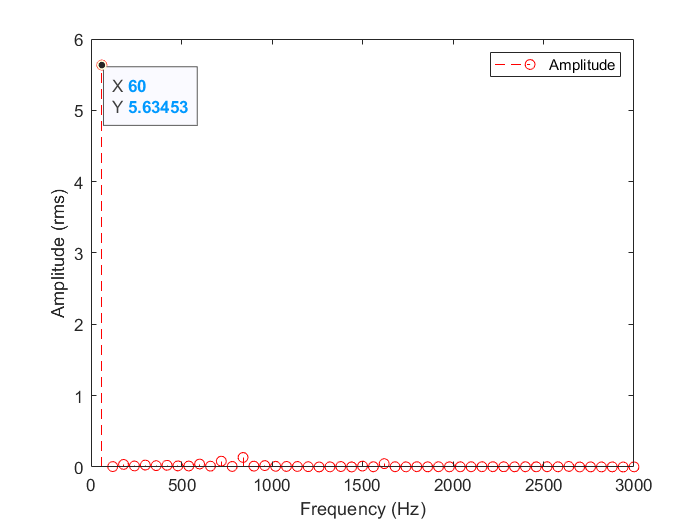

% Plot
inputs_plot = outputs; 
plot_rms(inputs_plot, 'rms')

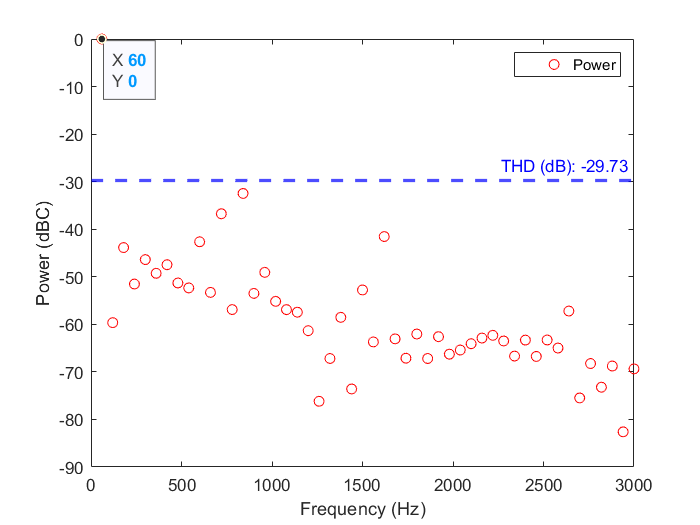

plot_rms(inputs_plot, 'dBc')

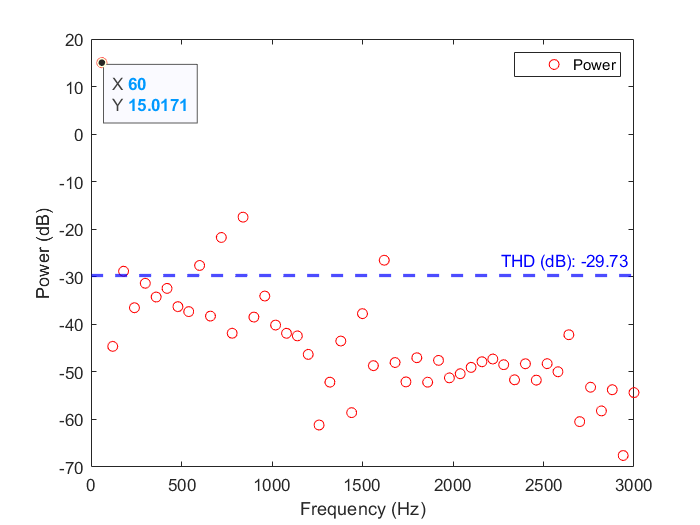

plot_rms(inputs_plot, 'dB')

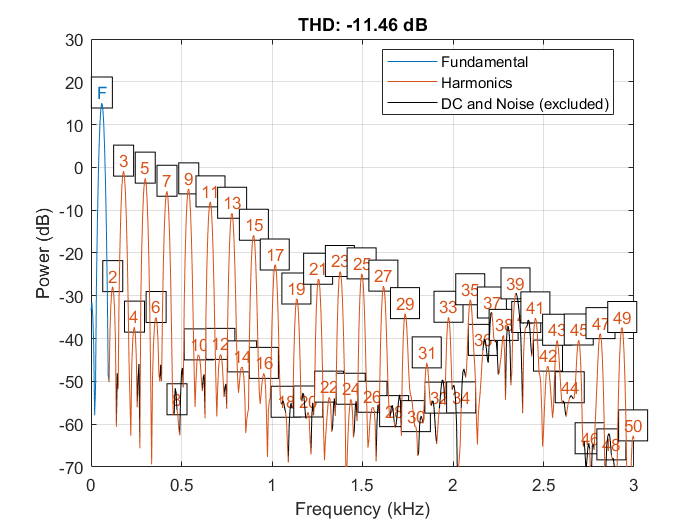

% Calcuating THD using MATLAB's built-in function
thd(data,fs,oh);
ax = gca; % current axes
ax.XLim = [0 3];

[THD_data, harmpow_data, harmfreq_data] = thd(data,fs, oh);